## Open or consolidate data files

clear
is_Mac = 1;
consolidate = 0;

if is_Mac
    save_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/database/general';
    data_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/database/single';
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw')) %addpath(genpath('.\sw'))
else
    save_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\database\general';
    data_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\database\single';
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
%database_header = ["ID","Item","Windspeed[m/s]","Airspeed[m/s]","Skew[deg]","Skew_sp[deg]","Mot_Status","Excitation","Mx[Nm]","My[Nm]","Mz[Nm]","Fx[N]","Fy[N]","Fz[N]","Mot_F[pwm]","Mot_R[pwm]","Mot_B[pwm]","Mot_L[pwm]","Ail_L[pwm]","Ail_R[pwm]","Elev[pwm]","Rud[pwm]","Pitch[deg]"];    
database_header = ["ID","Item","Windspeed","Airspeed","Skew","Skew_sp","Mot_Status","Excitation","Mx","My","Mz","Fx","Fy","Fz","Mot_F","Mot_R","Mot_B","Mot_L","Ail_L","Ail_R","Elev","Rud","Pitch"];
if consolidate
    xlsxFiles = dir(fullfile(data_path,'*.xlsx')); 
    numfiles = length(xlsxFiles);
    mydata = cell(1, numfiles);
    all    = [];
    for k = 1:numfiles 
      mydata{k} = xlsread(fullfile(data_path,xlsxFiles(k).name)); 
      all = [all;mydata{k}];
    end
    Table = array2table(all,'VariableNames',database_header);
    name = 'static_test_1.xlsx';
    table_path_format = fullfile(save_path,name);
    writetable(Table,table_path_format); 
else
    xlsxFiles = dir(fullfile(save_path,'*.xlsx'));
    all = xlsread(fullfile(save_path,xlsxFiles.name)); 
    Table = array2table(all,'VariableNames',database_header);
end


## Perform transformation from balance to drone c.g. and apply calibration

data = Table;

if is_Mac
    path = '/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/OJF/calibration';
else
    path = 'C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\OJF\calibration';
end
name = strcat('calibration.txt');
fid = fopen(fullfile(path,name));
format = sprintf('%s', repmat('%f', 1, 7));
calibration = cell2mat(textscan(fid, format,'Delimiter', ','));
fclose(fid);

for i =1:size(data,1)
    int_cal = interp1(calibration(:,1),calibration(:,2:end),data.Windspeed(i));
    data.Fx(i) = data.Fx(i)-int_cal(1);
    data.Fy(i) = data.Fy(i)-int_cal(2);
    data.Fz(i) = data.Fz(i)-int_cal(3);
    data.Mx(i) = data.Mx(i)-int_cal(4);
    data.My(i) = data.My(i)-int_cal(5);
    data.Mz(i) = data.Mz(i)-int_cal(6);
end

pole = [0,0,-1.04].'; %[0,0,-1]90.5+5.5+8
%pole = [0,0,0].'; 
m_i  = [data.Mx,data.My,data.Mz];
f_i  = [data.Fx,data.Fy,data.Fz];
m_e  = m_i + cross(f_i,pole.'.*ones(size(f_i)));
data.Mx = m_e(:,1);
data.My = m_e(:,2);
data.Mz = m_e(:,3);

## **Question to be answered**

*How can the effectiveness of the ailerons be modelled with skew, airspeed, mot cmd(check if can assume no).*

- Moment changes linearly with cmd to aerodynamic surface

- Moment changes with $\,{\sin \left(\Lambda \right)}^3$ 

- DO AIRSPEED CHECK

- DO MOT CMD CHECK

*How can the effectiveness of the tail be modelled with skew(check if can assume no), airspeed, mot cmd(check if can assume no), push cmd(check if can assume no). *

- Moment changes linearly with cmd to aerodynamic surface

- Moment does not change significantly with skew angle

- DO AIRSPEED

- DO MOT CMD CHECK

- Moment slope increases with push cmd

*How can lift be modelled with respect to airspeed, skew, pitch and mot cmd(check if can assume no). *

- Best fit of Lift with ${\left(\sin \left(\Lambda \right)v\right)}^2 +k$

- DO PITCH CURVE

- DO MOT CHECK

*Yawing moment and Roll moment from rotating the wing*

**LEFT AILERON - Idle motors - Roll Moment**

The inital model has the form of:


$$b_{\mathrm{al}} \,k_{\mathrm{al}} \,v^2 \,{\sin \left(\Lambda \right)}^3$$


ans =    -0.0007    1.0417


ans =    -0.0014    2.1963


ans =    -0.0024    3.6715


ans =    -0.0032    4.5490


ans =    -0.0029    4.3273


ans =     0.0000   -0.0110


ans =     0.0001   -0.1646


ans =     0.0003   -0.4079


ans =     0.0004   -0.6245


ans =     0.0004   -0.6851


ans =    -0.0001    0.0694


ans =    -0.0001    0.1305


ans =    -0.0002    0.1897


ans =    -0.0001    0.1516


ans =    -0.0001    0.1262


ans =     0.0000   -0.0026


ans =     0.0002   -0.2560


ans =     0.0002   -0.2605


ans =     0.0002   -0.3009


ans =     0.0003   -0.3346


ans =    -0.0001    0.0899


ans =    -0.0001    0.2429


ans =    -0.0004    0.4955


ans =    -0.0007    0.8530


ans =    -0.0008    1.1857


ans =    -0.0014    2.2009


ans =    -0.0027    4.1222


ans =    -0.0042    6.4259


ans =    -0.0054    7.6137


ans =    -0.0047    6.9568


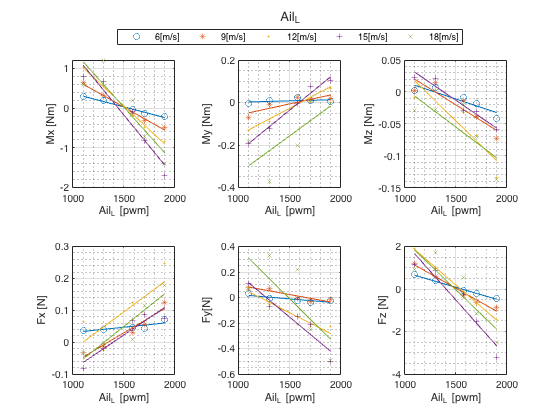

ans =    -0.0007    1.0728


ans =    -0.0014    2.0617


ans =    -0.0022    3.1811


ans =    -0.0031    4.6761


ans =    -0.0012    1.6485


ans =     0.0001   -0.0658


ans =     0.0001   -0.1171


ans =     0.0001   -0.2209


ans =     0.0003   -0.4676


ans =     0.0000   -0.1614


ans =    -0.0001    0.1264


ans =    -0.0001    0.2442


ans =    -0.0002    0.3398


ans =    -0.0002    0.4003


ans =    -0.0002    0.2934


ans =    -0.0001    0.2055


ans =    -0.0003    0.4952


ans =    -0.0005    0.7405


ans =    -0.0004    0.7396


ans =    -0.0006    1.0197


ans = 1×2
    0.0000   -0.0110


ans = 1×2
   -0.0001    0.1324


ans = 1×2
   -0.0003    0.2916


ans = 1×2
   -0.0006    0.7586


ans = 1×2
    0.0003   -0.5088


ans = 1×2
    0.0013   -1.9289


ans = 1×2
    0.0024   -3.4192


ans = 1×2
    0.0039   -5.5506


ans = 1×2
    0.0052   -7.7019


ans = 1×2
    0.0044   -7.3053


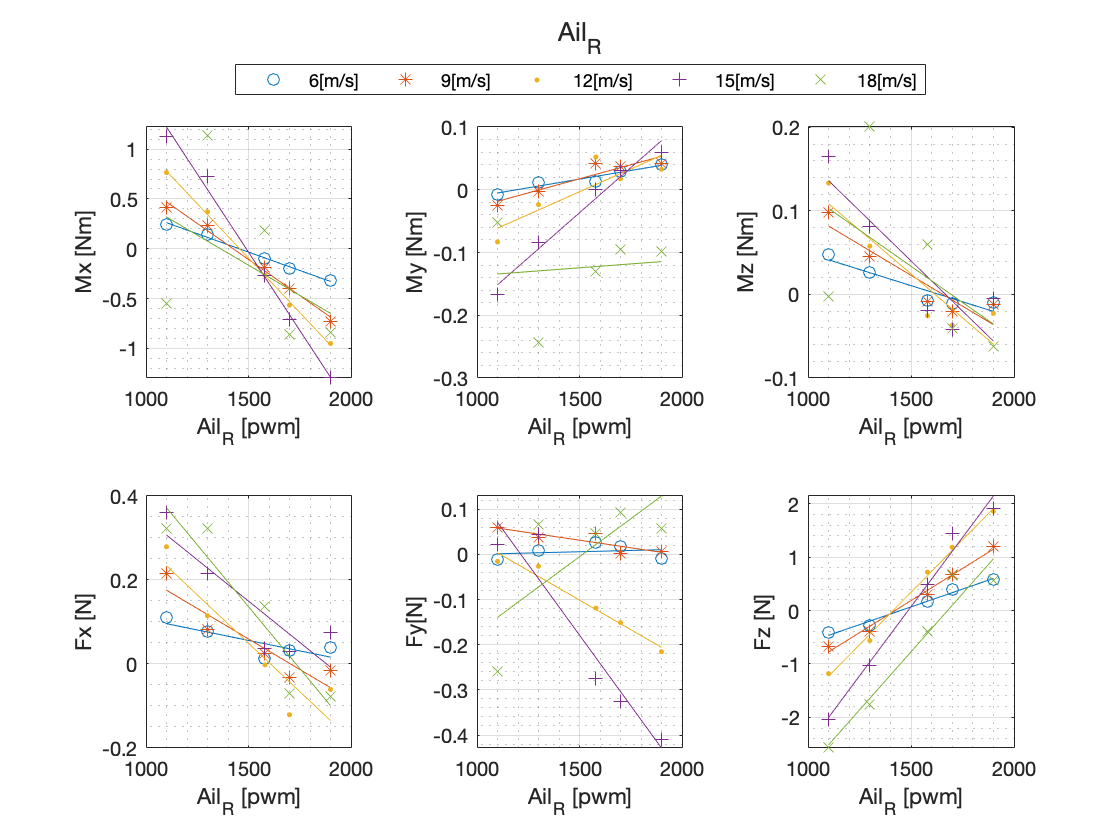

ans = 1×2
   -0.0001    0.0723


ans = 1×2
   -0.0001    0.1494


ans = 1×2
   -0.0004    0.5250


ans = 1×2
   -0.0004    0.5348


ans = 1×2
    0.0014   -1.7283


ans = 1×2
    0.0016   -2.2915


ans = 1×2
    0.0032   -4.7382


ans = 1×2
    0.0053   -7.9233


ans = 1×2
    0.0065   -9.8593


ans = 1×2
    0.0036   -6.2099


ans = 1×2
   -0.0000    0.0563


ans = 1×2
   -0.0001    0.1325


ans = 1×2
   -0.0002    0.2198


ans = 1×2
   -0.0002    0.2767


ans = 1×2
   -0.0001    0.2017


ans = 1×2
   -0.0002    0.3995


ans = 1×2
   -0.0004    0.8577


ans = 1×2
   -0.0006    1.3443


ans = 1×2
   -0.0008    1.8500


ans = 1×2
   -0.0007    1.4171


ans = 1×2
   -0.0001    0.0846


ans = 1×2
   -0.0002    0.2986


ans = 1×2
   -0.0003    0.3569


ans = 1×2
   -0.0005    0.7434


ans = 1×2
   -0.0003    0.5663


ans = 1×2
   -0.0027    3.9476


ans = 1×2
   -0.0052    7.5871


ans = 1×2
   -0.0085   12.6957


ans = 1×2
   -0.0100   15.0529


ans = 1×2
   -0.0065    9.5655


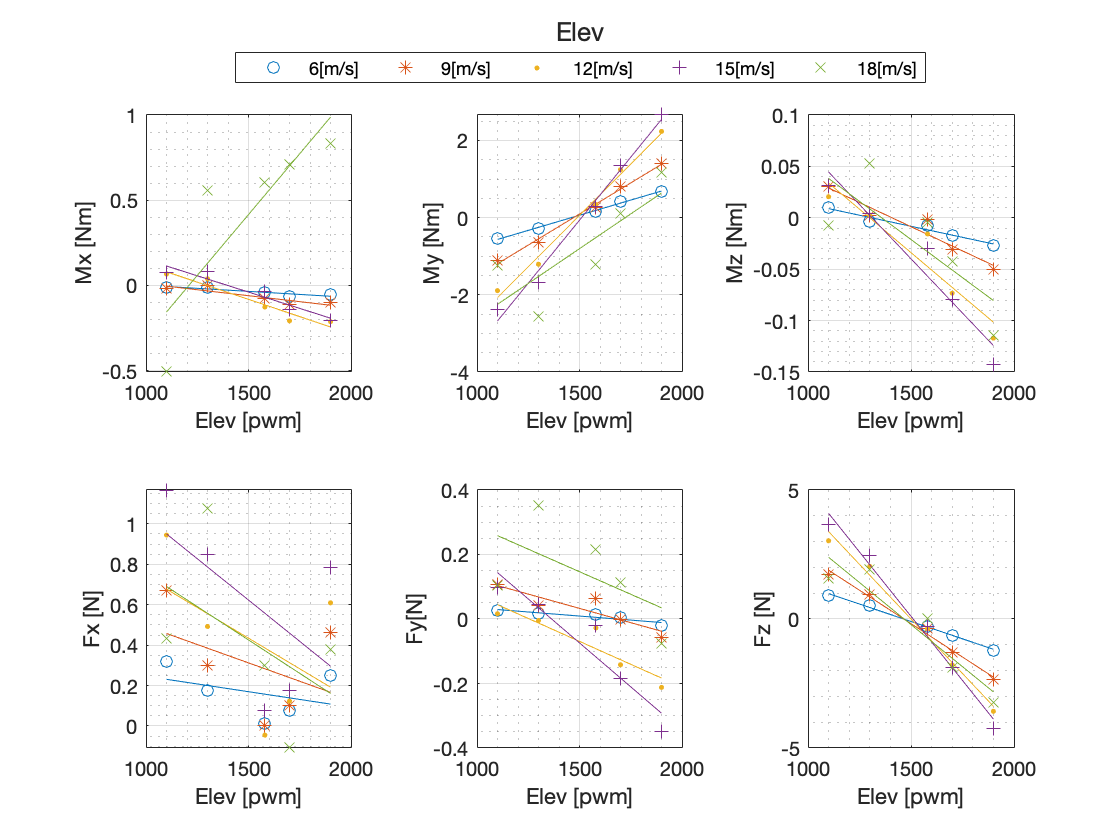

ans = 1×2
    0.0000   -0.0475


ans = 1×2
    0.0001   -0.1740


ans = 1×2
    0.0001   -0.2367


ans = 1×2
    0.0001   -0.1618


ans = 1×2
    0.0004    0.1604


ans = 1×2
    0.0000    0.0140


ans = 1×2
    0.0000    0.0127


ans = 1×2
    0.0001   -0.1216


ans = 1×2
    0.0000   -0.0697


ans = 1×2
   -0.0012    1.8625


ans = 1×2
    0.0003   -0.4257


ans = 1×2
    0.0006   -0.8987


ans = 1×2
    0.0011   -1.7490


ans = 1×2
    0.0016   -2.4013


ans = 1×2
    0.0016   -2.6169


ans = 1×2
   -0.0000    0.1064


ans = 1×2
    0.0000    0.0053


ans = 1×2
    0.0002   -0.1770


ans = 1×2
   -0.0000    0.1712


ans = 1×2
   -0.0002    0.4093


ans = 1×2
    0.0005   -0.7084


ans = 1×2
    0.0010   -1.4413


ans = 1×2
    0.0019   -2.9746


ans = 1×2
    0.0026   -4.0213


ans = 1×2
    0.0025   -3.7960


ans = 1×2
   -0.0001    0.1280


ans = 1×2
    0.0000   -0.0204


ans = 1×2
    0.0001    0.0159


ans = 1×2
   -0.0002    0.3884


ans = 1×2
    0.0022   -5.3958


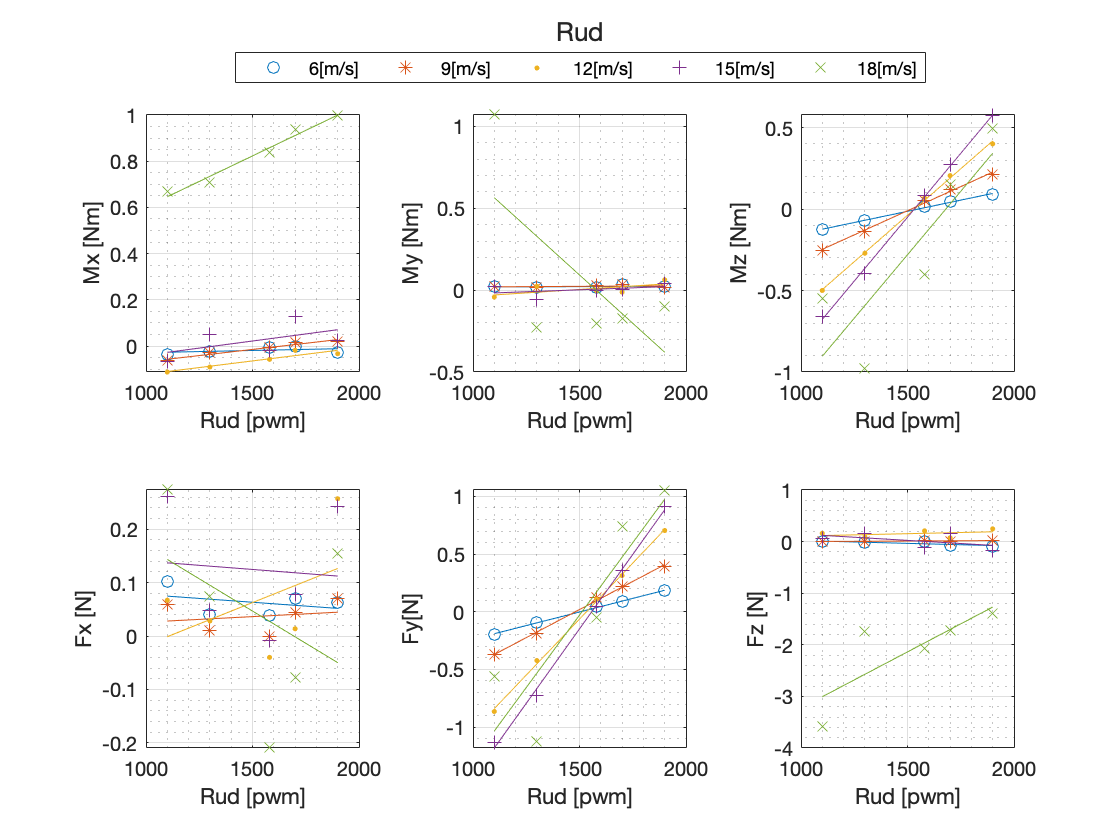

v = unique(data.Windspeed);
unit_header = ["ID","Item","Windspeed [m/s]","Airspeed [m/s]","Skew [deg]","Skew_sp [deg]","Mot_Status","Excitation","Mx [Nm]","My [Nm]","Mz [Nm]","Fx [N]","Fy[N]","Fz [N]","Mot_F [pwm]","Mot_R [pwm]","Mot_B [pwm]","Mot_L [pwm]","Ail_L [pwm]","Ail_R [pwm]","Elev [pwm]","Rud [pwm]","Pitch [deg]"];    
leg_v = [];
for i=1:max(size(v))
    leg_v= [leg_v,strcat(string(round(v(i))),'[m/s]'),''];
end
for k=0:3
    figure(k+1)
    clf
    cla
    t = tiledlayout(2,3);
    for j=9:14
        nexttile
        for i=1:max(size(v))
            out  = table_sifter(data,[-1,k,v(i),-1,-1,90,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            bias = table_sifter(data,[-1,5,v(i),-1,-1,90,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            plot_special(out.(19+k),out.(j)-bias.(j),1,i)
        end
        xlabel(unit_header(19+k))
        ylabel(unit_header(j))
        
        grid on
        grid minor

    end
    lgd = legend(leg_v,'NumColumns',5);
    lgd.Layout.Tile = 'north';
    title(t,out.Properties.VariableNames(19+k))
end

ans = 2×1
    1.0580
   -0.0162


ans = 2×1
    0.5547
   -0.0006


ans = 2×1
   -0.1760
   -0.0236


ans = 2×1
   -0.4800
   -0.0304


ans = 2×1
   -0.8737
   -0.0131


ans = 2×1
   -0.1732
   -0.1471


ans = 2×1
   -0.0790
   -0.0914


ans = 2×1
    0.0507
    0.0132


ans = 2×1
    0.0550
    0.0610


ans = 2×1
    0.1183
    0.0935


ans = 2×1
   -0.0087
    0.0061


ans = 2×1
    0.0032
    0.0059


ans = 2×1
   -0.0338
    0.0006


ans = 2×1
   -0.0737
   -0.0000


ans = 2×1
   -0.1412
   -0.0153


ans = 2×1
    0.0045
    0.0149


ans = 2×1
   -0.0438
   -0.0044


ans = 2×1
    0.0426
    0.0055


ans = 2×1
    0.0891
   -0.0030


ans = 2×1
    0.2841
   -0.0454


ans = 2×1
    0.0579
    0.0387


ans = 2×1
   -0.0413
    0.0276


ans = 2×1
   -0.2312
    0.0702


ans = 2×1
   -0.2355
    0.0568


ans = 2×1
   -0.2154
   -0.0114


ans = 2×1
    1.9446
    0.0047


ans = 2×1
    0.9566
   -0.0383


ans = 2×1
   -0.1224
   -0.1581


ans = 2×1
   -0.6564
   -0.2158


ans = 2×1
   -1.2807
   -0.2419


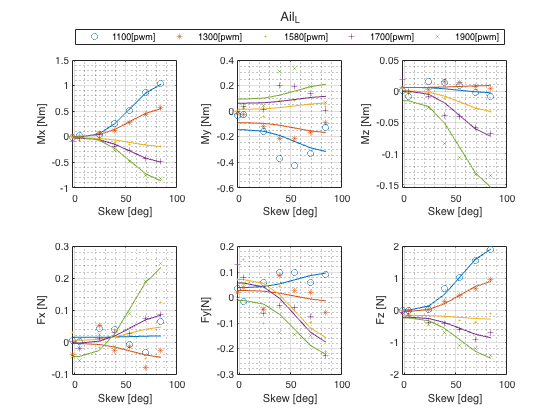

ans = 2×1
    0.8426
    0.0674


ans = 2×1
    0.4160
    0.0506


ans = 2×1
   -0.3181
   -0.0046


ans = 2×1
   -0.6860
   -0.0039


ans = 2×1
   -1.1340
   -0.0414


ans = 2×1
   -0.0975
   -0.2205


ans = 2×1
   -0.0258
   -0.1250


ans = 2×1
    0.0868
    0.0251


ans = 2×1
    0.1057
    0.0732


ans = 2×1
    0.1621
    0.1551


ans = 2×1
    0.1323
    0.0349


ans = 2×1
    0.0532
    0.0184


ans = 2×1
   -0.0291
   -0.0005


ans = 2×1
   -0.0370
   -0.0032


ans = 2×1
   -0.0211
   -0.0042


ans = 2×1
    0.3117
   -0.0238


ans = 2×1
    0.1485
   -0.0408


ans = 2×1
   -0.0279
   -0.0181


ans = 2×1
   -0.1433
    0.0197


ans = 2×1
   -0.1716
    0.0761


ans = 2×1
   -0.0013
    0.0334


ans = 2×1
   -0.0162
    0.0283


ans = 2×1
   -0.1098
    0.0313


ans = 2×1
   -0.1461
    0.0115


ans = 2×1
   -0.2615
    0.0155


ans = 2×1
   -1.3274
   -0.4918


ans = 2×1
   -0.6896
   -0.3174


ans = 2×1
    0.7626
   -0.0908


ans = 2×1
    1.3862
    0.0072


ans = 2×1
    2.1888
    0.1465


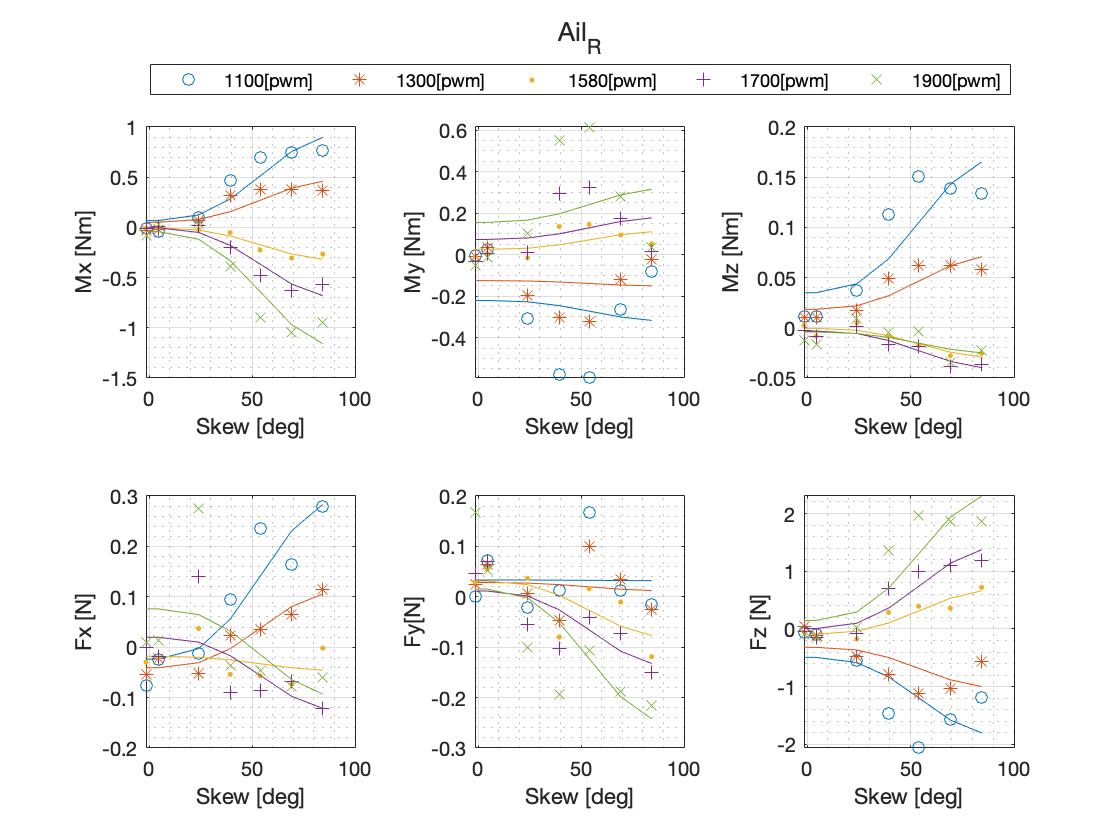

ans = 1×2
    0.0005    0.0288


ans = 1×2
    0.0001    0.0253


ans = 1×2
   -0.0011   -0.0302


ans = 1×2
   -0.0009   -0.1486


ans = 1×2
   -0.0008   -0.1724


ans = 1×2
   -0.0032   -1.6246


ans = 1×2
   -0.0026   -0.9667


ans = 1×2
    0.0004    0.3379


ans = 1×2
    0.0008    1.1393


ans = 1×2
    0.0009    2.1718


ans = 1×2
   -0.0002    0.0426


ans = 1×2
   -0.0001    0.0204


ans = 1×2
   -0.0001   -0.0091


ans = 1×2
   -0.0002   -0.0468


ans = 1×2
    0.0001   -0.1156


ans = 1×2
   -0.0017    1.0417


ans = 1×2
   -0.0009    0.5272


ans = 1×2
   -0.0007    0.0048


ans = 1×2
   -0.0001    0.1186


ans = 1×2
   -0.0011    0.7397


ans = 1×2
   -0.0014    0.1171


ans = 1×2
   -0.0011    0.0882


ans = 1×2
   -0.0004   -0.0440


ans = 1×2
   -0.0014   -0.0515


ans = 1×2
   -0.0011   -0.1645


ans = 1×2
    0.0079    2.2076


ans = 1×2
    0.0067    1.2546


ans = 1×2
    0.0025   -0.7301


ans = 1×2
    0.0035   -2.1026


ans = 1×2
    0.0023   -3.8689


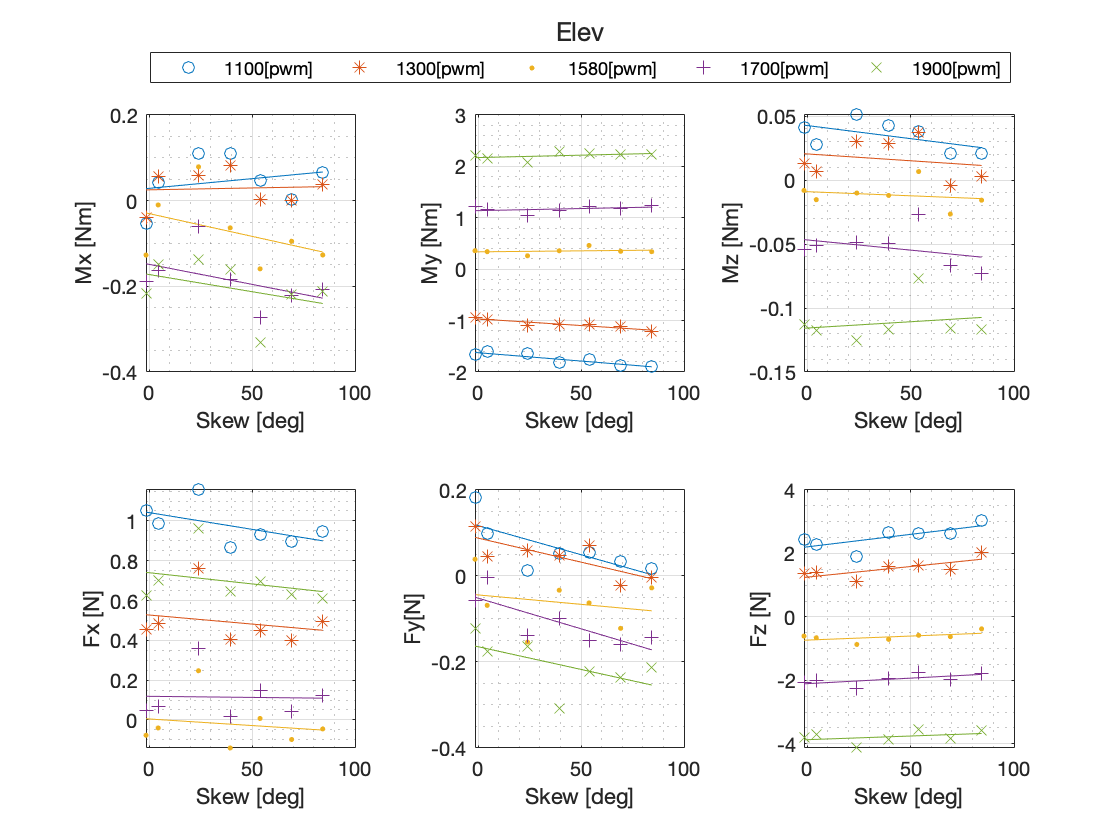

ans = 1×2
   -0.0007   -0.0462


ans = 1×2
   -0.0009   -0.0118


ans = 1×2
   -0.0001   -0.0324


ans = 1×2
   -0.0003    0.0060


ans = 1×2
   -0.0005    0.0504


ans = 1×2
   -0.0004    0.0265


ans = 1×2
    0.0003    0.0030


ans = 1×2
   -0.0002    0.0375


ans = 1×2
    0.0002    0.0128


ans = 1×2
    0.0009   -0.0029


ans = 1×2
   -0.0002   -0.4257


ans = 1×2
    0.0001   -0.2342


ans = 1×2
   -0.0001    0.0819


ans = 1×2
    0.0002    0.1997


ans = 1×2
    0.0008    0.3769


ans = 1×2
   -0.0008    0.1549


ans = 1×2
   -0.0004    0.0494


ans = 1×2
   -0.0014    0.0870


ans = 1×2
   -0.0008    0.1048


ans = 1×2
    0.0004    0.2114


ans = 1×2
   -0.0016   -0.7029


ans = 1×2
   -0.0003   -0.3983


ans = 1×2
   -0.0019    0.2154


ans = 1×2
   -0.0012    0.3783


ans = 1×2
    0.0002    0.6490


ans = 1×2
    0.0040   -0.2436


ans = 1×2
    0.0035   -0.2330


ans = 1×2
    0.0045   -0.2705


ans = 1×2
    0.0028   -0.2046


ans = 1×2
    0.0036   -0.2084


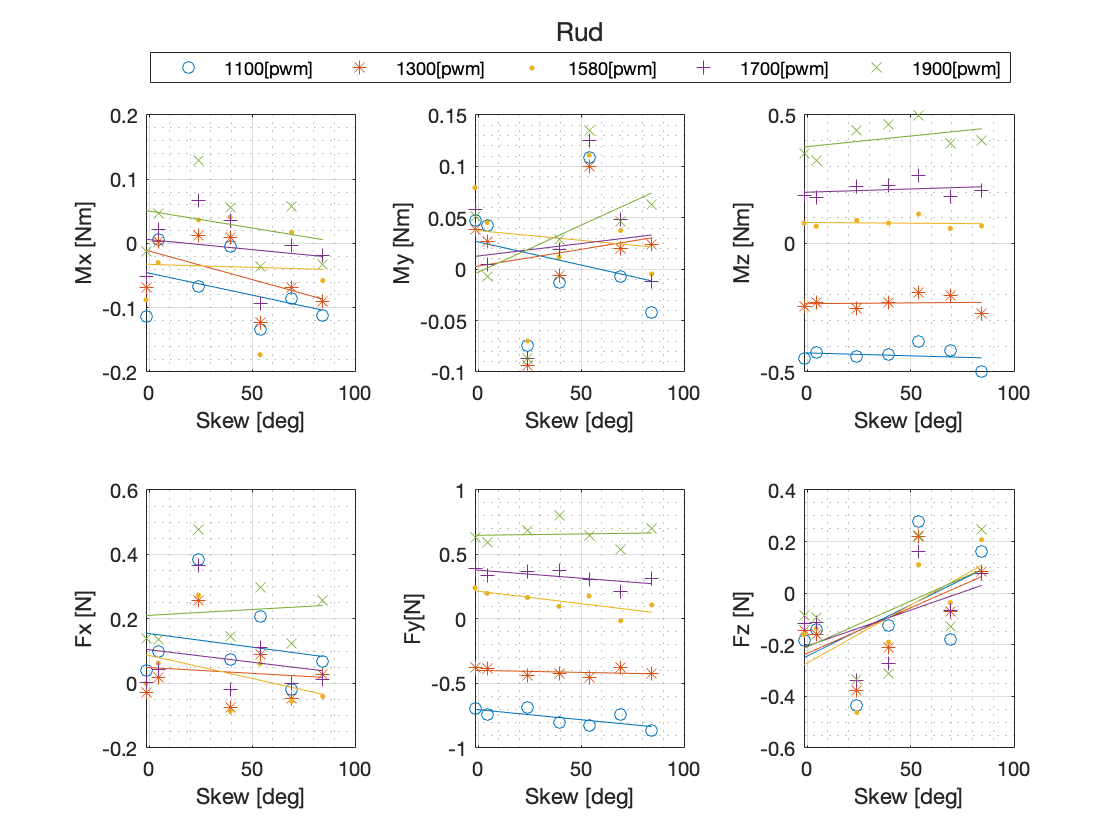

baseline = k;
cmd_idx = unique(data.Excitation);
cmd = [1100,1300,1580,1700,1900];
leg_cmd = [];
for i=1:max(size(cmd))
    leg_cmd= [leg_cmd,strcat(string(round(cmd(i))),'[pwm]'),''];
end
for k=0:3
    figure(baseline+k+1)
    clf
    cla
    t = tiledlayout(2,3);
    if k < 2
        order = 12;
    else
        order=1;
    end
    for j=9:14
        nexttile
        for i=1:max(size(cmd_idx))
            out  = table_sifter(data,[-1,k,v(3),-1,-1,-1,0,cmd_idx(i),-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            bias = table_sifter(data,[-1,5,v(3),-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            plot_special(out.(5),out.(j)-bias.(j),order,i)
        end
        xlabel(unit_header(5))
        ylabel(unit_header(j))
        
        grid on
        grid minor
        hold off

    end
    lgd = legend(leg_cmd,'NumColumns',5);
    lgd.Layout.Tile = 'north';
    title(t,out.Properties.VariableNames(19+k))
end

baseline = baseline+k;
%for k=0:3
    figure(baseline+k+1)
    clf
    cla
    t = tiledlayout(2,3);
    order=10;
    for j=9:14
        nexttile
        for i=1:max(size(v))
            out  = table_sifter(data,[-1,5,v(i),-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
            plot_special(out.(5),out.(j),order,i)
        end
        xlabel(unit_header(5))
        ylabel(unit_header(j))
        
        grid on
        grid minor
        

    end

ans = 2×1
   -0.0874
   -0.0922


ans = 2×1
    0.0268
   -0.1019


ans = 2×1
    0.1297
   -0.0734


ans = 2×1
    0.2662
   -0.1817


ans = 2×1
   -0.1231
   -0.1485


ans = 2×1
    0.0250
   -0.4261


ans = 2×1
    0.0466
   -1.0114


ans = 2×1
    0.0606
   -1.8687


ans = 2×1
    0.3382
   -2.9377


ans = 2×1
    0.8838
   -4.3461


ans = 2×1
    0.0116
   -0.0108


ans = 2×1
    0.0091
    0.0404


ans = 2×1
    0.0581
    0.0864


ans = 2×1
   -0.1298
    0.2272


ans = 2×1
    0.0944
    0.1609


ans = 2×1
   -0.2264
    1.3717


ans = 2×1
   -0.5531
    3.0797


ans = 2×1
   -0.3312
    5.4134


ans = 2×1
   -0.4146
    8.4918


ans = 2×1
    0.8874
   12.1584


ans = 2×1
    0.0288
    0.1771


ans = 2×1
   -0.0166
    0.2512


ans = 2×1
   -0.0666
    0.3275


ans = 2×1
    0.1722
    0.5176


ans = 2×1
   -0.0469
    0.8631


ans = 2×1
   -2.8203
   -0.3583


ans = 2×1
   -6.2564
   -0.5706


ans = 2×1
  -10.6758
   -0.8487


ans = 2×1
  -13.2031
   -2.5679


ans = 2×1
  -14.6884
   -5.3147


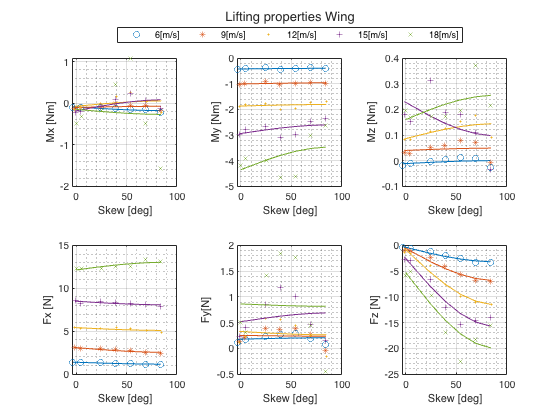

    lgd = legend(leg_v,'NumColumns',5);
    lgd.Layout.Tile = 'north';
    title(t,'Lifting properties Wing')
    hold off

%end
% L = 0.5 rho Cl S v^2 sin^2
L = 0.5 * 1.225 * 1.56 * 0.235 ;

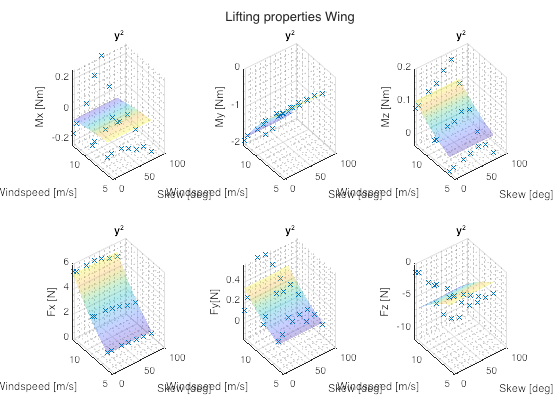


baseline = baseline+k;
figure(baseline+k+1)
clf
cla
t = tiledlayout(2,3);
order=10;
rmse_log = {};
coeffs = {};
for j=9:14
    nexttile
    prefilter = data(data.Windspeed<14,:);
    %prefilter = data;
    out  = table_sifter(prefilter,[-1,5,-1,-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
    %p = [sin(deg2rad(x)).^(order-9),ones(size(x))]\y;
    %plot_special(out.(5),out.(j),order,i)
    %scatter3(out.(5),out.(3),out.(j),'*')
    [rmse_log_i,coeffs_i] = plot3_special(out.(5),out.(3),out.(j),1,5);
    rmse_log{j-8} = rmse_log_i;
    coeffs{j-8}   = coeffs_i;
    xlabel(unit_header(5))
    ylabel(unit_header(3))
    zlabel(unit_header(j))    
    grid on
    grid minor
    hold off
end
%lgd = legend(leg_v,'NumColumns',5);
%lgd.Layout.Tile = 'north';
title(t,'Lifting properties Wing')

Study on the effect of the motors on the effectiveness of the aerodynamic surfaces

baseline = baseline+k;  
mot_stat = unique(data.Mot_Status);
leg_mot_stat = [];
leg_skew_sp = [];
leg_v = [];
skew_q = unique(data.Skew_sp);
folder = fullfile(pwd,'plots_save');
lin_coefs = [];
for i=1:max(size(mot_stat))
    leg_mot_stat= [leg_mot_stat,strcat('mot status: ',string(mot_stat(i))),''];
end
for i=1:max(size(skew_q))
    leg_skew_sp= [leg_skew_sp,strcat(string(skew_q(i)),'[deg]')];
end
for i=1:max(size(v))
    leg_v= [leg_v,strcat(string(round(v(i))),'[m/s]')];
end
count = 1;
for q=1:max(size(skew_q))
    for m=1:max(size(v))
        for k=0:3
            tit = '';
            %f=figure(baseline+count,'visible','off')
            f=figure('visible','off');
            clf
            cla
            t = tiledlayout(2,3);
            for j=9:14
                nexttile
                for i=1:max(size(mot_stat))
                    out  = table_sifter(data,[-1,k,v(m),-1,-1,skew_q(q),mot_stat(i),-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
                    bias = table_sifter(data,[-1,5,v(m),-1,-1,skew_q(q),mot_stat(i),-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
                    coefs= plot_special(out.(19+k),out.(j)-bias.(j),1,i);
                    lin_coefs = [lin_coefs;[v(m),skew_q(q),mot_stat(i),k,j,coefs(1),coefs(2)]];
                    
                end
                xlabel(unit_header(19+k))
                ylabel(unit_header(j))
                
                grid on
                grid minor
        
            end
            lgd = legend(leg_mot_stat,'NumColumns',5);
            lgd.Layout.Tile = 'north';
            tit = title(t,strcat(out.Properties.VariableNames(19+k),"-",leg_v(m),"-",leg_skew_sp(q)));
            tit2 = strcat(out.Properties.VariableNames(19+k),"__v__",num2str(v(m)),"__skew__",num2str(skew_q(q)));
            hold off
            count = count+1
            %saveas(f,fullfile(folder,strcat(tit.String,'.jpg')))
            saveas(f,fullfile(folder,strcat(tit2,'.jpg')))
        end
    end
end

count = 2

count = 3

count = 4

count = 5

count = 6

count = 7

count = 8

count = 9

count = 10

count = 11

count = 12

count = 13

count = 14

count = 15

count = 16

count = 17

count = 18

count = 19

count = 20

count = 21

count = 22

count = 23

count = 24

count = 25

count = 26

count = 27

count = 28

count = 29

count = 30

count = 31

count = 32

count = 33

count = 34

count = 35

count = 36

count = 37

count = 38

count = 39

count = 40

count = 41

count = 42

count = 43

count = 44

lin_coefs2 = lin_coefs;
lin_coefs2(:,1) = round(lin_coefs2(:,1));
lin_table = array2table(lin_coefs2,'VariableNames',["v","skew","mot_status","AS","force_moment","m","k"]);
temp = lin_table(lin_table.v<16,:);
temp = table_sifter(temp,[-1,-1,0,2,10,-1,-1]);
%p = lsqr([p1,p2,ones(size(x))],z); 